# PRM + MPC en un entorno dinamico

Ensambla los modulos del proyecto TFM_RobotNavigation para ejecutar una simulacion completa de la arquitectura PRM + MPC. El planificador global utiliza una roadmap PRM persistente: se construye una sola vez con la geometria estatica y se reutiliza en las consultas posteriores desde la posicion actual del robot. MPC recibe el objetivo adelantado comun, predice el comportamiento del robot y de los obstaculos y genera el control [v w]. El robot se integra mediante el mismo modelo de uniciclo [x y theta]. La visualizacion conserva la misma estructura: los objetos se crean una vez, se actualizan sin clf y el arbol grafico reducido de la consulta PRM anterior se sustituye completamente cuando existe una nueva consulta.

clearvars;
clc;
close all;

## Opciones de la ejecucion

Cambie solamente estas opciones para ejecutar otra demostracion.

modoEjecucion = "visual";       % "visual" o "batch"
idEscenario = "alta";          % "baja", "media" o "alta"
semilla = 7;

% La pausa solo modifica la velocidad con la que se observa la animacion;
% no modifica el periodo fisico de muestreo de la simulacion.
factorVelocidadAnimacion = 1.0;  % 1 = tiempo simulado aproximado

% Exportacion y guardado son opcionales. Permanecen desactivados durante el
% desarrollo para no mezclar su coste con los tiempos de los algoritmos.
exportarAnimacion = false;
formatoAnimacion = "mp4";        % "mp4", "m4v", "avi" o "gif"
guardarResultado = false;

## Localizacion de la raiz y configuracion del path

En los Live Scripts, mfilename puede devolver el nombre de un helper temporal del Live Editor en lugar de la ruta real del archivo. Por ello, la fuente principal de la raiz es el proyecto MATLAB actualmente abierto.

raizProyecto = '';

try
    proyectoAbierto = matlab.project.rootProject;
catch
    proyectoAbierto = [];
end

if ~isempty(proyectoAbierto)
    raizProyecto = char(proyectoAbierto.RootFolder);
end

% Fallback para poder ejecutar el script aunque el proyecto no este abierto.
% Se prueba primero la ubicacion del documento activo y despues pwd.
if isempty(raizProyecto)
    carpetasIniciales = {pwd};

    try
        rutaActiva = matlab.desktop.editor.getActiveFilename;

        if ~isempty(rutaActiva)
            carpetasIniciales = [ ...
                {fileparts(rutaActiva)}, ...
                carpetasIniciales];
        end
    catch
        % MATLAB Online puede no exponer esta funcion en todos los contextos.
    end

    for iInicio = 1:numel(carpetasIniciales)
        carpetaCandidata = carpetasIniciales{iInicio};

        for nivel = 1:10
            estructuraValida = ...
                isfolder(fullfile(carpetaCandidata,'config')) && ...
                isfolder(fullfile(carpetaCandidata,'planificadores')) && ...
                isfolder(fullfile(carpetaCandidata,'controladores')) && ...
                isfolder(fullfile(carpetaCandidata,'simulacion')) && ...
                isfolder(fullfile(carpetaCandidata,'metricas')) && ...
                isfolder(fullfile(carpetaCandidata,'visualizacion')) && ...
                isfolder(fullfile(carpetaCandidata,'herramientas'));

            if estructuraValida
                raizProyecto = carpetaCandidata;
                break;
            end

            carpetaPadre = fileparts(carpetaCandidata);

            if isempty(carpetaPadre) || ...
                    strcmp(carpetaPadre,carpetaCandidata)
                break;
            end

            carpetaCandidata = carpetaPadre;
        end

        if ~isempty(raizProyecto)
            break;
        end
    end
end

if isempty(raizProyecto)
    error('ejecutar_prm_mpc:RaizNoEncontrada', ...
        ['No se pudo identificar la raiz del proyecto. Abra el archivo ' ...
         'TFM_RobotNavigation.prj o establezca como carpeta actual la ' ...
         'raiz que contiene config, main, planificadores y controladores.']);
end

carpetasProyecto = [ ...
    "config", ...
    "planificadores", ...
    "controladores", ...
    "simulacion", ...
    "metricas", ...
    "visualizacion", ...
    "herramientas"];

for iCarpeta = 1:numel(carpetasProyecto)
    carpetaModulo = fullfile( ...
        raizProyecto,carpetasProyecto(iCarpeta));

    if ~isfolder(carpetaModulo)
        error('ejecutar_prm_mpc:CarpetaAusente', ...
            'No existe la carpeta requerida: %s',char(carpetaModulo));
    end

    addpath(char(carpetaModulo),'-begin');
end

rehash path;
fprintf('Raiz del proyecto: %s\n',raizProyecto);

Raiz del proyecto: /MATLAB Drive/TFM




% Comprobacion temprana de las dependencias utilizadas por este main.
funcionesNecesarias = [ ...
    "parametros_generales", ...
    "escenarios", ...
    "configuracion_robot", ...
    "prm", ...
    "consulta_prm", ...
    "seguimiento_trayectoria", ...
    "mpc", ...
    "actualizar_obstaculos", ...
    "replanificacion", ...
    "modelo_robot", ...
    "detectar_colisiones", ...
    "resultados", ...
    "inicializar_figura", ...
    "dibujar_entorno", ...
    "dibujar_robot", ...
    "actualizar_graficos", ...
    "exportar_animacion"];

for iFuncion = 1:numel(funcionesNecesarias)
    if isempty(which(char(funcionesNecesarias(iFuncion))))
        error('ejecutar_prm_mpc:DependenciaAusente', ...
            'No se encontro la funcion %s.m en el path del proyecto.', ...
            funcionesNecesarias(iFuncion));
    end
end

## Configuracion comun, escenario y robot

cfg = parametros_generales(modoEjecucion);
cfg.semilla = semilla;
cfg.nombreArquitectura = "PRM + MPC";
cfg.planificador = @prm;
cfg.controlador = @mpc;

if ~isnumeric(factorVelocidadAnimacion) || ...
        ~isscalar(factorVelocidadAnimacion) || ...
        ~isfinite(factorVelocidadAnimacion) || ...
        factorVelocidadAnimacion <= 0
    error('ejecutar_prm_mpc:FactorAnimacionNoValido', ...
        'factorVelocidadAnimacion debe ser un escalar positivo.');
end

if cfg.visual.activa
    cfg.visual.pausa = true;
    cfg.visual.tPausa = ...
        cfg.sim.Ts/factorVelocidadAnimacion;
end

escenario = escenarios(idEscenario);
robot = configuracion_robot();

% La semilla se fija en el main para que la construccion de la roadmap
% PRM y el resto de arquitecturas sean reproducibles.
rng(cfg.semilla,'twister');

## Construccion inicial de la roadmap PRM persistente

La roadmap contiene exclusivamente la geometria estatica. Su coste se registra como inicializacion y no como tiempo del controlador.

relojTotal = tic;
relojConstruccionPRM = tic;

[roadmapPRM,infoConstruccionPRM] = prm( ...
    escenario.meta, ...
    escenario.limites, ...
    escenario.obstaculosEstaticos, ...
    robot, ...
    cfg);

tiempoConstruccionPRM = toc(relojConstruccionPRM);

if ~infoConstruccionPRM.roadmapUtilizable
    warning('ejecutar_prm_mpc:RoadmapInicialDebil', ...
        ['La roadmap inicial no contiene una componente utilizable ' ...
         'conectada con la meta. Las consultas y la ampliacion ' ...
         'excepcional intentaran recuperar la conectividad.']);
end

## Inicializacion del estado y de los historiales

estadoRobot = escenario.inicio;
numeroRecuperacionesColision = 0;
enColisionDinamicaAnterior = false;
obstaculosDinamicos = escenario.obstaculosDinamicos;
caminoGlobal = zeros(0,2);
caminoGlobalEsParcial = false;

infoConsultaPRM = struct();
infoExpansionPRM = struct();
infoMPC = struct();

% El MPC penaliza los cambios respecto al control realmente aplicado en el
% paso anterior. Se actualiza despues de resolver colisiones y saturaciones.
controlAnterior = robot.controlInicial;
infoSeguimiento = struct();
infoReplanificacion = struct();
infoColision = struct();

siguientePasoPermitido = 1;
maxPasos = cfg.terminacion.maxPasos;
numeroDinamicos = numel(obstaculosDinamicos);

trayectoriaEjecutada = nan(maxPasos+1,3);
trayectoriaEjecutada(1,:) = estadoRobot;

controlesAplicados = nan(maxPasos,2);

historialObstaculos = ...
    nan(maxPasos+1,numeroDinamicos,2);

for iObstaculo = 1:numeroDinamicos
    historialObstaculos(1,iObstaculo,:) = reshape( ...
        obstaculosDinamicos(iObstaculo).pos,1,1,2);
end

% Los valores NaN indican que una fase no fue ejecutada en ese paso.
tiempoPlanificacion = nan(maxPasos,1);
tiempoControl = nan(maxPasos,1);
tiempoCiclo = nan(maxPasos,1);
tiempoVisualizacion = nan(maxPasos,1);

planificacionEjecutada = false(maxPasos,1);
controlEjecutado = false(maxPasos,1);

% Diagnosticos complementarios del planificador, del controlador y del seguimiento.
mpcFactiblePorPaso = false(maxPasos,1);
riesgoPredichoPorPaso = false(maxPasos,1);
colisionPredichaPorPaso = false(maxPasos,1);
distanciaMinimaPredichaPorPaso = nan(maxPasos,1);
costeMPCPorPaso = nan(maxPasos,1);
numeroCandidatosFactiblesPorPaso = nan(maxPasos,1);
fraccionCandidatosFactiblesPorPaso = nan(maxPasos,1);
numeroViolacionesSeguridadPorPaso = nan(maxPasos,1);

distanciaAlCaminoPorPaso = nan(maxPasos,1);
motivoMPCPorPaso = strings(maxPasos,1);
motivoCiclo = strings(maxPasos,1);
motivoPRM = strings(maxPasos,1);
motivoExpansionPRM = strings(maxPasos,1);
motivoReplanificacion = strings(maxPasos,1);
motivoSeguimiento = strings(maxPasos,1);
caminoParcialPorPaso = false(maxPasos,1);

expansionPRMEjecutada = false(maxPasos,1);
numeroAristasBloqueadasPRM = nan(maxPasos,1);
fraccionAristasBloqueadasPRM = nan(maxPasos,1);
numeroConexionesInicioPRM = nan(maxPasos,1);
numeroNodosRoadmapPRM = nan(maxPasos,1);
numeroAristasRoadmapPRM = nan(maxPasos,1);

numeroPlanificaciones = 0;
numeroConsultasPRM = 0;
numeroReplanificaciones = 0;
numeroFallosPlanificacion = 0;
numeroEpisodiosSinCandidatoFactible = 0;
numeroEpisodiosRiesgoPredicho = 0;
numeroEpisodiosColisionPredicha = 0;
numeroRecuperacionesColision = 0;
numeroAproximacionesParciales = 0;

fallosConsultaConsecutivos = 0;
maximoFallosConsultaConsecutivos = 0;

enFalloFactibilidadAnterior = false;
enRiesgoPredichoAnterior = false;
enColisionPredichaAnterior = false;
enColisionDinamicaAnterior = false;

pasosEjecutados = 0;
metaAlcanzada = ...
    norm(estadoRobot(1:2)-escenario.meta) <= ...
        cfg.navegacion.radioMeta;
colisionOcurrida = false;

vistaPlanificador = struct( ...
    'actualizar',false, ...
    'nodos',zeros(0,2), ...
    'aristas',zeros(0,2));

## Inicializacion diferida de la visualizacion y la exportacion

La figura se crea dentro del primer ciclo de simulacion. De este modo no se genera un resultado independiente de iteracion cero y el Live Editor puede registrar los drawnow del bucle como fotogramas reproducibles.

graficos = struct();
graficos.activa = false;
graficosInicializados = false;

exportacion = struct();
infoExportacion = struct();
archivoAnimacion = "";
exportacionIniciada = false;

% La configuracion del archivo se prepara ahora, pero el escritor solo se
% abre despues de crear la figura durante la primera iteracion.
if exportarAnimacion
    extension = lower(strtrim(string(formatoAnimacion)));

    if ~any(extension == ["mp4","m4v","avi","gif"])
        error('ejecutar_prm_mpc:FormatoAnimacionNoValido', ...
            'El formato debe ser mp4, m4v, avi o gif.');
    end

    nombreAnimacion = "prm_mpc_"+string(escenario.id)+ ...
        "_semilla_"+string(cfg.semilla)+"."+extension;

    archivoAnimacion = fullfile( ...
        raizProyecto,"salidas","animaciones",nombreAnimacion);

    opcionesExportacion = struct();
    opcionesExportacion.activa = true;
    opcionesExportacion.sobrescribir = true;
    opcionesExportacion.factorVelocidad = ...
        factorVelocidadAnimacion;
    opcionesExportacion.calidad = 90;
    opcionesExportacion.capturarSoloActualizaciones = true;
    opcionesExportacion.bloquearRedimensionado = true;
    opcionesExportacion.eliminarSiVacio = true;
    opcionesExportacion.mostrarMensajes = false;
else
    opcionesExportacion = struct();
end

## Simulacion PRM + MPC

try
    for k = 1:maxPasos
        pasosEjecutados = k;
        relojCiclo = tic;

        textoEstado = "Navegacion";
        mpcFactibleActual = true;
        riesgoPredichoActual = false;
        colisionPredichaActual = false;
        controlSolicitado = robot.controlParada;
        motivoPRM(k) = "no_ejecutado";
        motivoExpansionPRM(k) = "no_ejecutada";
        motivoMPCPorPaso(k) = "control_no_ejecutado";

        vistaPlanificador = struct( ...
            'actualizar',false, ...
            'nodos',zeros(0,2), ...
            'aristas',zeros(0,2));

## Movimiento de los obstaculos dinamicos

        obstaculosDinamicos = actualizar_obstaculos( ...
            obstaculosDinamicos, ...
            escenario.obstaculosEstaticos, ...
            escenario.limites, ...
            cfg.sim.Ts);

        for iObstaculo = 1:numeroDinamicos
            historialObstaculos(k+1,iObstaculo,:) = reshape( ...
                obstaculosDinamicos(iObstaculo).pos,1,1,2);
        end

## Decision global de replanificacion

Para mantener la misma filosofia que RRT* + MPC, los obstaculos moviles se gestionan localmente mediante MPC. La roadmap y sus consultas globales utilizan solamente limites y obstaculos fijos.

        dinamicosParaPlanificacion = obstaculosDinamicos([]);

        [debeReplanificar,infoReplanificacion] = replanificacion( ...
            caminoGlobal, ...
            estadoRobot, ...
            k, ...
            robot, ...
            escenario.obstaculosEstaticos, ...
            dinamicosParaPlanificacion, ...
            escenario.limites, ...
            cfg, ...
            siguientePasoPermitido);

        motivoReplanificacion(k) = ...
            string(infoReplanificacion.motivo);

        if debeReplanificar
            caminoAnterior = caminoGlobal;
            eraPlanificacionInicial = numeroPlanificaciones == 0;

            relojPlanificacion = tic;

            [caminoCandidato,infoConsultaPRM] = consulta_prm( ...
                roadmapPRM, ...
                estadoRobot, ...
                dinamicosParaPlanificacion, ...
                robot, ...
                cfg);

            numeroConsultasPRM = numeroConsultasPRM+1;

            if infoConsultaPRM.exito
                fallosConsultaConsecutivos = 0;
            else
                fallosConsultaConsecutivos = ...
                    fallosConsultaConsecutivos+1;

                maximoFallosConsultaConsecutivos = max( ...
                    maximoFallosConsultaConsecutivos, ...
                    fallosConsultaConsecutivos);
            end

            % Tras varios fallos consecutivos se amplia excepcionalmente la
            % roadmap existente. No se reconstruye desde cero ni se pierden
            % sus nodos y aristas anteriores.
            debeAmpliarRoadmap = ...
                ~infoConsultaPRM.exito && ...
                fallosConsultaConsecutivos >= ...
                    cfg.prm.ampliarTrasFallos && ...
                roadmapPRM.numeroExpansiones < ...
                    cfg.prm.maxExpansiones;

            if debeAmpliarRoadmap
                [roadmapPRM,infoExpansionPRM] = prm( ...
                    escenario.meta, ...
                    escenario.limites, ...
                    escenario.obstaculosEstaticos, ...
                    robot, ...
                    cfg, ...
                    roadmapPRM, ...
                    estadoRobot);

                expansionPRMEjecutada(k) = true;
                motivoExpansionPRM(k) = ...
                    string(infoExpansionPRM.motivo);

                % La consulta se repite inmediatamente sobre la roadmap ya
                % ampliada. El tiempo de ambas operaciones queda incluido
                % en el mismo ciclo de planificacion.
                [caminoCandidato,infoConsultaPRM] = consulta_prm( ...
                    roadmapPRM, ...
                    estadoRobot, ...
                    dinamicosParaPlanificacion, ...
                    robot, ...
                    cfg);

                numeroConsultasPRM = numeroConsultasPRM+1;
                fallosConsultaConsecutivos = 0;

                if ~infoConsultaPRM.exito
                    fallosConsultaConsecutivos = 1;
                end
            end

            tiempoPlanificacion(k) = toc(relojPlanificacion);
            planificacionEjecutada(k) = true;
            motivoPRM(k) = string(infoConsultaPRM.motivo);
            numeroPlanificaciones = numeroPlanificaciones+1;

            if ~eraPlanificacionInicial
                numeroReplanificaciones = ...
                    numeroReplanificaciones+1;
            end

            % consulta_prm devuelve un arbol grafico reducido del componente
            % alcanzable desde el robot. Se representa incluso si la
            % consulta falla, sustituyendo la vista anterior.
            vistaPlanificador = infoConsultaPRM.vistaPlanificador;

            numeroAristasBloqueadasPRM(k) = ...
                infoConsultaPRM.numeroAristasBloqueadas;
            fraccionAristasBloqueadasPRM(k) = ...
                infoConsultaPRM.fraccionAristasBloqueadas;
            numeroConexionesInicioPRM(k) = ...
                infoConsultaPRM.numeroConexionesTemporalesInicio;
            numeroNodosRoadmapPRM(k) = roadmapPRM.numeroNodos;
            numeroAristasRoadmapPRM(k) = roadmapPRM.numeroAristas;

            if infoConsultaPRM.exito
                caminoGlobal = caminoCandidato;
                caminoGlobalEsParcial = false;
                siguientePasoPermitido = k+1;

                if eraPlanificacionInicial
                    textoEstado = "Consulta PRM inicial";
                elseif expansionPRMEjecutada(k)
                    textoEstado = "Consulta tras expansion PRM";
                else
                    textoEstado = "Nueva consulta PRM";
                end
            else
                numeroFallosPlanificacion = ...
                    numeroFallosPlanificacion+1;

                siguientePasoPermitido = ...
                    k+cfg.replan.reintento;

                % Un fallo puntual nunca destruye una ruta completa previa.
                if size(caminoAnterior,1) >= 2
                    caminoGlobal = caminoAnterior;
                    textoEstado = ...
                        "Consulta PRM fallida: ruta anterior";
                else
                    caminoGlobal = zeros(0,2);
                    textoEstado = "Sin camino global PRM";
                end
            end

        elseif infoReplanificacion.solicitada && ...
                ~infoReplanificacion.permitida
            textoEstado = "Esperando reintento";
        end

## Objetivo local comun sobre la trayectoria global

        [objetivoLocal,caminoGlobal,infoSeguimiento] = ...
            seguimiento_trayectoria( ...
                estadoRobot,caminoGlobal,escenario.meta,cfg,false);

        motivoSeguimiento(k) = string(infoSeguimiento.motivo);
        caminoGlobalEsParcial = false;
        caminoParcialPorPaso(k) = false;

        if isfield(infoSeguimiento,'distanciaAlCamino')
            distanciaAlCaminoPorPaso(k) = ...
                infoSeguimiento.distanciaAlCamino;
        end

## Colision instantanea antes del control

        [hayColisionAntesControl,infoColisionAntesControl] = ...
            detectar_colisiones( ...
                estadoRobot, ...
                robot, ...
                escenario.obstaculosEstaticos, ...
                obstaculosDinamicos, ...
                escenario.limites);

        colisionDinamicaAntesControl = ...
            infoColisionAntesControl.colisionDinamicos;

        colisionNoDinamicaAntesControl = ...
            infoColisionAntesControl.colisionLimites || ...
            infoColisionAntesControl.colisionEstaticos;

## Control local MPC

        if colisionDinamicaAntesControl
            % Durante el contacto fisico con un movil, el robot espera.
            % La ruta global se conserva y el MPC vuelve a evaluarse cuando
            % el obstaculo deja de solaparse con el robot.
            controlSolicitado = robot.controlParada;
            textoEstado = "Esperando separacion del dinamico";

        elseif colisionNoDinamicaAntesControl
            % Esta rama protege frente a un estado numericamente invalido.
            controlSolicitado = robot.controlParada;
            textoEstado = "Reorientacion junto a obstaculo fijo";

        elseif infoSeguimiento.caminoUtilizable && ...
                ~infoSeguimiento.metaAlcanzada

            relojControl = tic;

            [controlSolicitado,infoMPC] = mpc( ...
                estadoRobot, ...
                objetivoLocal, ...
                escenario.meta, ...
                escenario.obstaculosEstaticos, ...
                obstaculosDinamicos, ...
                escenario.limites, ...
                robot, ...
                cfg, ...
                controlAnterior);

            tiempoControl(k) = toc(relojControl);
            controlEjecutado(k) = true;
            motivoMPCPorPaso(k) = string(infoMPC.motivo);

            % infoMPC.exito indica que existe al menos un candidato que
            % respeta todos los umbrales durante el horizonte. Si es false,
            % mpc.m devuelve aun el candidato menos penalizado.
            mpcFactibleActual = logical(infoMPC.exito);
            riesgoPredichoActual = logical(infoMPC.prediceRiesgo);
            colisionPredichaActual = ...
                logical(infoMPC.prediceColisionFisica);

            mpcFactiblePorPaso(k) = mpcFactibleActual;
            riesgoPredichoPorPaso(k) = riesgoPredichoActual;
            colisionPredichaPorPaso(k) = colisionPredichaActual;
            distanciaMinimaPredichaPorPaso(k) = ...
                infoMPC.distanciaMinimaPredicha;
            costeMPCPorPaso(k) = infoMPC.costeOptimo;
            numeroCandidatosFactiblesPorPaso(k) = ...
                infoMPC.numeroCandidatosFactibles;
            fraccionCandidatosFactiblesPorPaso(k) = ...
                infoMPC.fraccionCandidatosFactibles;
            numeroViolacionesSeguridadPorPaso(k) = ...
                infoMPC.numeroViolacionesSeguridad;

            if colisionPredichaActual
                textoEstado = "MPC: colision predicha";
            elseif ~mpcFactibleActual
                textoEstado = "MPC sin candidato factible";
            elseif riesgoPredichoActual
                textoEstado = "MPC: margen comprometido";
            end
        else
            controlSolicitado = robot.controlParada;

            if infoSeguimiento.metaAlcanzada
                textoEstado = "Meta alcanzada";
            elseif isempty(caminoGlobal) && textoEstado == "Navegacion"
                textoEstado = "Sin camino global";
            end
        end

        % Conteo de episodios predictivos del MPC.
        falloFactibilidadActual = ...
            controlEjecutado(k) && ~mpcFactibleActual;

        if falloFactibilidadActual && ...
                ~enFalloFactibilidadAnterior
            numeroEpisodiosSinCandidatoFactible = ...
                numeroEpisodiosSinCandidatoFactible+1;
        end

        enFalloFactibilidadAnterior = falloFactibilidadActual;

        riesgoActualRegistrado = ...
            controlEjecutado(k) && riesgoPredichoActual;

        if riesgoActualRegistrado && ~enRiesgoPredichoAnterior
            numeroEpisodiosRiesgoPredicho = ...
                numeroEpisodiosRiesgoPredicho+1;
        end

        enRiesgoPredichoAnterior = riesgoActualRegistrado;

        colisionActualRegistrada = ...
            controlEjecutado(k) && colisionPredichaActual;

        if colisionActualRegistrada && ...
                ~enColisionPredichaAnterior
            numeroEpisodiosColisionPredicha = ...
                numeroEpisodiosColisionPredicha+1;
        end

        enColisionPredichaAnterior = colisionActualRegistrada;

## Modelo cinematico, contacto y recuperacion

        estadoAnterior = estadoRobot;

        if colisionDinamicaAntesControl
            % No se retrocede ni se borra la ruta. Los obstaculos se
            % actualizaran otra vez al comienzo del siguiente ciclo.
            estadoRobot = estadoAnterior;
            controlAplicado = robot.controlParada;
            infoColision = infoColisionAntesControl;

        else
            [estadoCandidato,controlCandidato,~] = modelo_robot( ...
                estadoAnterior,controlSolicitado,cfg.sim.Ts,robot);

            [~,infoColisionCandidata] = detectar_colisiones( ...
                estadoCandidato, ...
                robot, ...
                escenario.obstaculosEstaticos, ...
                obstaculosDinamicos, ...
                escenario.limites);

            colisionFijaCandidata = ...
                infoColisionCandidata.colisionLimites || ...
                infoColisionCandidata.colisionEstaticos;

            if colisionFijaCandidata
                % El paso de traslacion se rechaza, pero el robot gira en
                % el sitio hacia el objetivo local o, en su defecto, la meta.
                vectorRecuperacion = ...
                    objetivoLocal-estadoAnterior(1:2);

                if norm(vectorRecuperacion) <= 1e-12
                    vectorRecuperacion = ...
                        escenario.meta-estadoAnterior(1:2);
                end

                anguloRecuperacion = atan2( ...
                    vectorRecuperacion(2),vectorRecuperacion(1));

                errorRecuperacion = wrap_to_pi_local( ...
                    anguloRecuperacion-estadoAnterior(3));

                % Se conserva, cuando sea util, el giro solicitado por
                % MPC. Si el candidato era recto, se aplica un giro hacia
                % el objetivo local limitado por la cinematica del robot.
                giroRecuperacion = controlCandidato(2);

                if abs(giroRecuperacion) <= 1e-12
                    giroRecuperacion = min(max( ...
                        errorRecuperacion/cfg.sim.Ts, ...
                        robot.limites.wMin), ...
                        robot.limites.wMax);
                end

                [estadoRobot,controlAplicado,~] = modelo_robot( ...
                    estadoAnterior,[0 giroRecuperacion], ...
                    cfg.sim.Ts,robot);

                [~,infoColision] = detectar_colisiones( ...
                    estadoRobot, ...
                    robot, ...
                    escenario.obstaculosEstaticos, ...
                    obstaculosDinamicos, ...
                    escenario.limites);

                textoEstado = ...
                    "Paso fijo rechazado: reorientacion";
            else
                % El contacto dinamico se acepta y se registra. En el ciclo
                % siguiente el robot esperara hasta que el movil se aparte.
                estadoRobot = estadoCandidato;
                controlAplicado = controlCandidato;
                infoColision = infoColisionCandidata;

                if infoColision.colisionDinamicos
                    textoEstado = ...
                        "Contacto dinamico: espera en siguiente ciclo";
                end
            end
        end

        controlesAplicados(k,:) = controlAplicado;
        controlAnterior = controlAplicado;
        trayectoriaEjecutada(k+1,:) = estadoRobot;

        hayColision = infoColision.hayColision;
        colisionOcurrida = colisionOcurrida || hayColision;

        if infoColision.colisionDinamicos && ...
                ~enColisionDinamicaAnterior
            numeroRecuperacionesColision = ...
                numeroRecuperacionesColision+1;
        end

        enColisionDinamicaAnterior = ...
            infoColision.colisionDinamicos;

        metaAlcanzadaAhora = ...
            norm(estadoRobot(1:2)-escenario.meta) <= ...
                cfg.navegacion.radioMeta;

        metaAlcanzada = ...
            metaAlcanzada || metaAlcanzadaAhora;

        if metaAlcanzadaAhora
            textoEstado = "Meta alcanzada";
        end

        motivoCiclo(k) = textoEstado;

        % El cronometro del nucleo se detiene antes de cualquier operacion
        % grafica, captura de video o pausa intencionada.
        tiempoCiclo(k) = toc(relojCiclo);

## Visualizacion y captura fuera del tiempo computacional

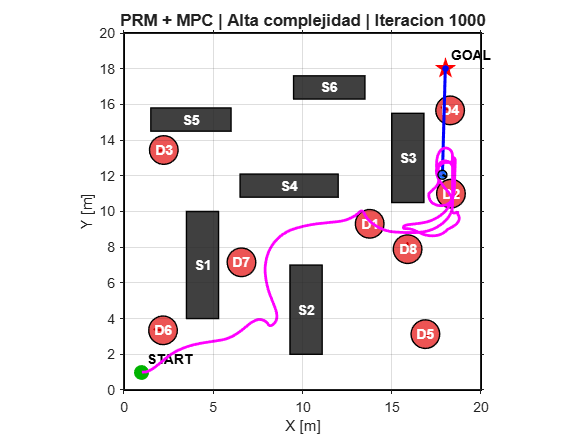

        if cfg.visual.activa
            relojVisualizacion = tic;

            % La figura se crea por primera vez dentro del bucle. No existe
            % una figura separada de inicializacion ni un fotograma cero.
            if ~graficosInicializados
                graficos = inicializar_figura( ...
                    escenario,cfg,cfg.nombreArquitectura);

                % Proteccion frente a versiones anteriores del modulo que
                % creaban la figura con Visible='off'.
                if isfield(graficos,'figura') && ...
                        isgraphics(graficos.figura,'figure')
                    set(graficos.figura,'Visible','on');
                end

                graficos = dibujar_entorno( ...
                    graficos,escenario,obstaculosDinamicos);

                graficos = dibujar_robot( ...
                    graficos,estadoRobot,robot);

                graficosInicializados = true;

                % La exportacion externa comienza una vez que existe una
                % figura valida. Todavia no se captura ningun fotograma.
                if exportarAnimacion
                    [exportacion,infoExportacion] = exportar_animacion( ...
                        "iniciar",[],graficos,cfg, ...
                        archivoAnimacion,opcionesExportacion);

                    exportacionIniciada = true;
                end
            end

            graficos = actualizar_graficos( ...
                graficos, ...
                k, ...
                estadoRobot, ...
                trayectoriaEjecutada(1:k+1,:), ...
                caminoGlobal, ...
                obstaculosDinamicos, ...
                vistaPlanificador, ...
                textoEstado);

            % Al ejecutarse dentro del bucle de un archivo .mlx con la
            % salida configurada como Inline, el Live Editor conserva los
            % estados y muestra Play, deslizador y velocidad al finalizar.
            drawnow;

            if exportarAnimacion && exportacionIniciada
                [exportacion,~] = exportar_animacion( ...
                    "capturar",exportacion,graficos);
            end

            tiempoVisualizacion(k) = ...
                toc(relojVisualizacion);

            if graficos.pausa && graficos.tPausa > 0
                pause(graficos.tPausa);
            end
        end

## Condiciones configuradas de terminacion

        if metaAlcanzadaAhora && ...
                cfg.terminacion.detenerEnMeta
            break;
        end

        if hayColision && ...
                cfg.terminacion.detenerEnColision
            break;
        end
    end

catch errorSimulacion
    % Evita dejar un archivo de video abierto o incompleto si la simulacion
    % se interrumpe por un error.
    if exportarAnimacion && exportacionIniciada && ...
            ~isempty(fieldnames(exportacion))
        try
            [exportacion,~] = exportar_animacion( ...
                "cancelar",exportacion);
        catch
            % Se conserva siempre el error original de la simulacion.
        end
    end

    rethrow(errorSimulacion);
end

## Finalizacion de la exportacion y tiempo real de reloj

if exportarAnimacion && exportacionIniciada
    [exportacion,infoExportacion] = exportar_animacion( ...
        "finalizar",exportacion);
end

tiempoRelojTotal = toc(relojTotal);

## Calculo normalizado de los resultados

registroTiempos = struct();
registroTiempos.planificacion = tiempoPlanificacion;
registroTiempos.control = tiempoControl;
registroTiempos.ciclo = tiempoCiclo;
registroTiempos.visualizacion = tiempoVisualizacion;
registroTiempos.planificacionEjecutada = planificacionEjecutada;
registroTiempos.controlEjecutado = controlEjecutado;
registroTiempos.inicializacion = tiempoConstruccionPRM;
registroTiempos.tiempoRelojTotal = tiempoRelojTotal;
registroTiempos.incluyeVisualizacion = false;
registroTiempos.incluyePausas = false;
registroTiempos.metaAlcanzada = metaAlcanzada;

registro = struct();
registro.arquitectura = cfg.nombreArquitectura;
registro.semilla = cfg.semilla;
registro.pasosEjecutados = pasosEjecutados;
registro.trayectoria = trayectoriaEjecutada;
registro.historialObstaculos = historialObstaculos;
registro.controles = controlesAplicados;
registro.tiempos = registroTiempos;
registro.numeroReplanificaciones = numeroReplanificaciones;
registro.numeroFallosPlanificacion = numeroFallosPlanificacion;
registro.caminoGlobalFinal = caminoGlobal;

[resultado,filaResultado] = resultados( ...
    registro,escenario,robot,cfg);

% Diagnosticos especificos de este main, adicionales a las metricas comunes.
resultado.contadores.numeroPlanificacionesMain = ...
    numeroPlanificaciones;
resultado.contadores.numeroConsultasPRM = ...
    numeroConsultasPRM;
resultado.contadores.numeroConstruccionesPRM = ...
    roadmapPRM.numeroConstrucciones;
resultado.contadores.numeroExpansionesPRM = ...
    roadmapPRM.numeroExpansiones;
resultado.contadores.numeroNodosRoadmapFinal = ...
    roadmapPRM.numeroNodos;
resultado.contadores.numeroAristasRoadmapFinal = ...
    roadmapPRM.numeroAristas;
resultado.contadores.maximoFallosConsultaConsecutivosPRM = ...
    maximoFallosConsultaConsecutivos;

resultado.contadores.numeroEpisodiosSinCandidatoFactibleMPC = ...
    numeroEpisodiosSinCandidatoFactible;
resultado.contadores.numeroPasosSinCandidatoFactibleMPC = ...
    nnz(controlEjecutado(1:pasosEjecutados) & ...
        ~mpcFactiblePorPaso(1:pasosEjecutados));
resultado.contadores.numeroEpisodiosRiesgoPredichoMPC = ...
    numeroEpisodiosRiesgoPredicho;
resultado.contadores.numeroPasosRiesgoPredichoMPC = ...
    nnz(riesgoPredichoPorPaso(1:pasosEjecutados));
resultado.contadores.numeroEpisodiosColisionPredichaMPC = ...
    numeroEpisodiosColisionPredicha;
resultado.contadores.numeroPasosColisionPredichaMPC = ...
    nnz(colisionPredichaPorPaso(1:pasosEjecutados));
resultado.contadores.numeroRecuperacionesColision = ...
    numeroRecuperacionesColision;
resultado.contadores.numeroAproximacionesParciales = ...
    numeroAproximacionesParciales;

resultado.historiales.mpcEjecutado = ...
    controlEjecutado(1:pasosEjecutados);
resultado.historiales.mpcFactible = ...
    mpcFactiblePorPaso(1:pasosEjecutados);
resultado.historiales.riesgoPredichoMPC = ...
    riesgoPredichoPorPaso(1:pasosEjecutados);
resultado.historiales.colisionPredichaMPC = ...
    colisionPredichaPorPaso(1:pasosEjecutados);
resultado.historiales.distanciaMinimaPredichaMPC = ...
    distanciaMinimaPredichaPorPaso(1:pasosEjecutados);
resultado.historiales.costeMPC = ...
    costeMPCPorPaso(1:pasosEjecutados);
resultado.historiales.numeroCandidatosFactiblesMPC = ...
    numeroCandidatosFactiblesPorPaso(1:pasosEjecutados);
resultado.historiales.fraccionCandidatosFactiblesMPC = ...
    fraccionCandidatosFactiblesPorPaso(1:pasosEjecutados);
resultado.historiales.numeroViolacionesSeguridadMPC = ...
    numeroViolacionesSeguridadPorPaso(1:pasosEjecutados);
resultado.historiales.motivoMPC = ...
    motivoMPCPorPaso(1:pasosEjecutados);

resultado.historiales.distanciaAlCamino = ...
    distanciaAlCaminoPorPaso(1:pasosEjecutados);
resultado.historiales.motivoCiclo = ...
    motivoCiclo(1:pasosEjecutados);
resultado.historiales.motivoPRM = ...
    motivoPRM(1:pasosEjecutados);
resultado.historiales.motivoExpansionPRM = ...
    motivoExpansionPRM(1:pasosEjecutados);
resultado.historiales.expansionPRMEjecutada = ...
    expansionPRMEjecutada(1:pasosEjecutados);
resultado.historiales.numeroAristasBloqueadasPRM = ...
    numeroAristasBloqueadasPRM(1:pasosEjecutados);
resultado.historiales.fraccionAristasBloqueadasPRM = ...
    fraccionAristasBloqueadasPRM(1:pasosEjecutados);
resultado.historiales.numeroConexionesInicioPRM = ...
    numeroConexionesInicioPRM(1:pasosEjecutados);
resultado.historiales.numeroNodosRoadmapPRM = ...
    numeroNodosRoadmapPRM(1:pasosEjecutados);
resultado.historiales.numeroAristasRoadmapPRM = ...
    numeroAristasRoadmapPRM(1:pasosEjecutados);
resultado.historiales.motivoReplanificacion = ...
    motivoReplanificacion(1:pasosEjecutados);
resultado.historiales.motivoSeguimiento = ...
    motivoSeguimiento(1:pasosEjecutados);
resultado.historiales.caminoParcialPorPaso = ...
    caminoParcialPorPaso(1:pasosEjecutados);

mascaraMPC = controlEjecutado(1:pasosEjecutados);

resultado.metricas.mpc = struct();
resultado.metricas.mpc.numeroEvaluaciones = nnz(mascaraMPC);

if any(mascaraMPC)
    factiblesMPC = ...
        mpcFactiblePorPaso(1:pasosEjecutados);
    factiblesMPC = factiblesMPC(mascaraMPC);

    distanciasMPC = ...
        distanciaMinimaPredichaPorPaso(1:pasosEjecutados);
    distanciasMPC = distanciasMPC(mascaraMPC);

    costesMPC = costeMPCPorPaso(1:pasosEjecutados);
    costesMPC = costesMPC(mascaraMPC);

    candidatosFactiblesMPC = ...
        numeroCandidatosFactiblesPorPaso(1:pasosEjecutados);
    candidatosFactiblesMPC = ...
        candidatosFactiblesMPC(mascaraMPC);

    resultado.metricas.mpc.porcentajeEvaluacionesFactibles = ...
        100*nnz(factiblesMPC)/numel(factiblesMPC);
    resultado.metricas.mpc.distanciaMinimaPredichaMinima = ...
        min(distanciasMPC,[],'omitnan');
    resultado.metricas.mpc.costeMedio = ...
        mean(costesMPC,'omitnan');
    resultado.metricas.mpc.candidatosFactiblesMedios = ...
        mean(candidatosFactiblesMPC,'omitnan');
else
    resultado.metricas.mpc.porcentajeEvaluacionesFactibles = NaN;
    resultado.metricas.mpc.distanciaMinimaPredichaMinima = NaN;
    resultado.metricas.mpc.costeMedio = NaN;
    resultado.metricas.mpc.candidatosFactiblesMedios = NaN;
end

resultado.metricas.mpc.numeroCandidatosNominal = ...
    cfg.mpc.nVelocidades*cfg.mpc.nGiros;
resultado.metricas.mpc.horizontePasos = cfg.mpc.Np;
resultado.metricas.mpc.horizontePrediccion_s = ...
    cfg.mpc.Np*cfg.sim.Ts;
resultado.metricas.mpc.criterioFactibilidad = ...
    "respeta_umbral_estatico_y_dinamico_en_todo_el_horizonte";
resultado.metricas.mpc.criterioSeleccionSinFactible = ...
    "menos_violaciones_menor_coste_mayor_continuidad_y_seguridad";

resultado.metricas.prm = struct();
resultado.metricas.prm.tiempoConstruccionInicial_s = ...
    tiempoConstruccionPRM;
resultado.metricas.prm.numeroNodosFinal = ...
    roadmapPRM.numeroNodos;
resultado.metricas.prm.numeroAristasFinal = ...
    roadmapPRM.numeroAristas;
resultado.metricas.prm.numeroConstrucciones = ...
    roadmapPRM.numeroConstrucciones;
resultado.metricas.prm.numeroExpansiones = ...
    roadmapPRM.numeroExpansiones;
resultado.metricas.prm.roadmapPersistente = true;
resultado.metricas.prm.dinamicosEnConsultaGlobal = false;

resultado.detalles.construccionInicialPRM = ...
    infoConstruccionPRM;
resultado.detalles.ultimaConsultaPRM = ...
    infoConsultaPRM;
resultado.detalles.ultimaExpansionPRM = ...
    infoExpansionPRM;
resultado.detalles.roadmapPRMFinal = ...
    roadmapPRM;
resultado.detalles.ultimoControlMPC = infoMPC;
resultado.detalles.ultimoSeguimiento = infoSeguimiento;
resultado.detalles.ultimaColisionEvaluada = infoColision;
resultado.detalles.controlAnteriorFinal = controlAnterior;

if exportarAnimacion && exportacionIniciada
    resultado.detalles.exportacion = infoExportacion;
end

## Guardado opcional

archivoResultadoMAT = "";
archivoResultadoCSV = "";

if guardarResultado
    carpetaResultados = fullfile( ...
        raizProyecto,"salidas","resultados");

    if exist(char(carpetaResultados),'dir') ~= 7
        mkdir(char(carpetaResultados));
    end

    nombreBase = "prm_mpc_"+string(escenario.id)+ ...
        "_semilla_"+string(cfg.semilla);

    archivoResultadoMAT = fullfile( ...
        carpetaResultados,nombreBase+".mat");

    archivoResultadoCSV = fullfile( ...
        carpetaResultados,nombreBase+".csv");

    save(char(archivoResultadoMAT), ...
        'resultado','filaResultado','registro', ...
        'cfg','escenario','robot','-v7.3');

    writetable(filaResultado,char(archivoResultadoCSV));
end

## Resumen mostrado en el Live Editor

disp(" ");

disp("Resumen de la ejecucion PRM + MPC");

Resumen de la ejecucion PRM + MPC


disp(filaResultado);

    Arquitectura    Escenario    Semilla    Exito    MetaAlcanzada    Colision           MotivoTerminacion           PasosEjecutados    TiempoSimulado_s    TiempoHastaMeta_s    Longitud_m    SuavidadRMS_1_m    DistanciaMinima_m    DistanciaFinalMeta_m    Planificaciones    Replanificaciones    FallosPlanificacion    EpisodiosRiesgo    EpisodiosColision    TiempoPlanificacionTotal_s    TiempoPlanificacionMedio_s    TiempoControlTotal_s    TiempoControlMedio_s    TiempoControlMaximo_s    TiempoCicloMedio_s    TiempoCicloMaximo_s    TiempoComputoT


disp("Construcciones de roadmap PRM: "+ ...
    string(roadmapPRM.numeroConstrucciones));

Construcciones de roadmap PRM: 1


disp("Expansiones de roadmap PRM: "+ ...
    string(roadmapPRM.numeroExpansiones));

Expansiones de roadmap PRM: 0


disp("Consultas PRM realizadas: "+ ...
    string(numeroConsultasPRM));

Consultas PRM realizadas: 111


disp("Episodios sin candidato factible MPC: "+ ...
    string(numeroEpisodiosSinCandidatoFactible));

Episodios sin candidato factible MPC: 6


disp("Pasos con riesgo predicho por MPC: "+ ...
    string(nnz(riesgoPredichoPorPaso(1:pasosEjecutados))));

Pasos con riesgo predicho por MPC: 37


disp("Pasos con colision fisica predicha por MPC: "+ ...
    string(nnz(colisionPredichaPorPaso(1:pasosEjecutados))));

Pasos con colision fisica predicha por MPC: 24



if exportarAnimacion && exportacionIniciada
    disp("Animacion: "+string(infoExportacion.archivo));
end

if guardarResultado
    disp("Resultado MAT: "+string(archivoResultadoMAT));
    disp("Resultado CSV: "+string(archivoResultadoCSV));
end